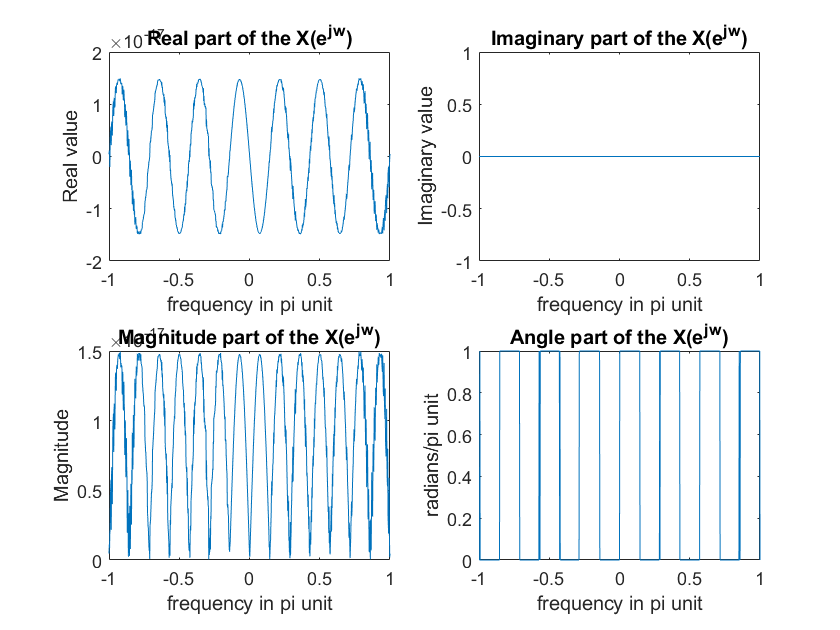

% M=[5 15 25 100];
M=15;
w0=pi/2;
K=500;
n=50;
n=-n:n;
[rect,rn]=unitseq(min(n),M,0);
x=cos(w0*n);%.*rect;
[x,n]=sigmult(x,n,rect,rn);
[X,w]=dtft(x,n,K)

%Given X(e^jw0)
xr1=0.5*cos(((w-w0)*(M-1))/2).*(sin((w-w0).*M/2)/sin((w-w0)/2));
xr2=0.5*cos(((w+w0)*(M-1))/2).*(sin((w-(2*pi-w0)).*M/2)/sin((w-(2*pi-w0))/2));
xr=xr1+xr2;

figure(1)
% dfp4(X,w)
figure(2)
dfp4(xr,w)